# Create a NODE Lookup table

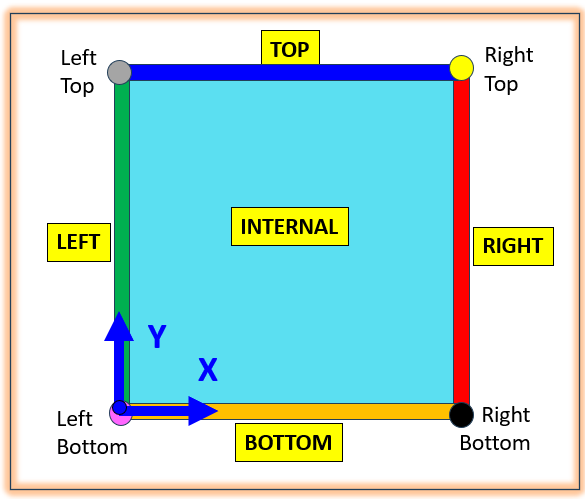

### INPUTS:

- `x_grid :` the X values of the grid points in the X-direction

- `y_grid :` the Y values of the grid points in the Y-direction

- name,value pairs for optional inouts arguments:   `mode=table`   OR  `mode=dictionary `OR  `mode=cell`

### OUTPUTS:

- `NODE_name_list` : a string array containing the NODE names 

- `NODE_PROP_LOOKUP` : either a table or a dictionary of a cell array

## NOTE:

- `NODE_name_list` will be presenting in this order

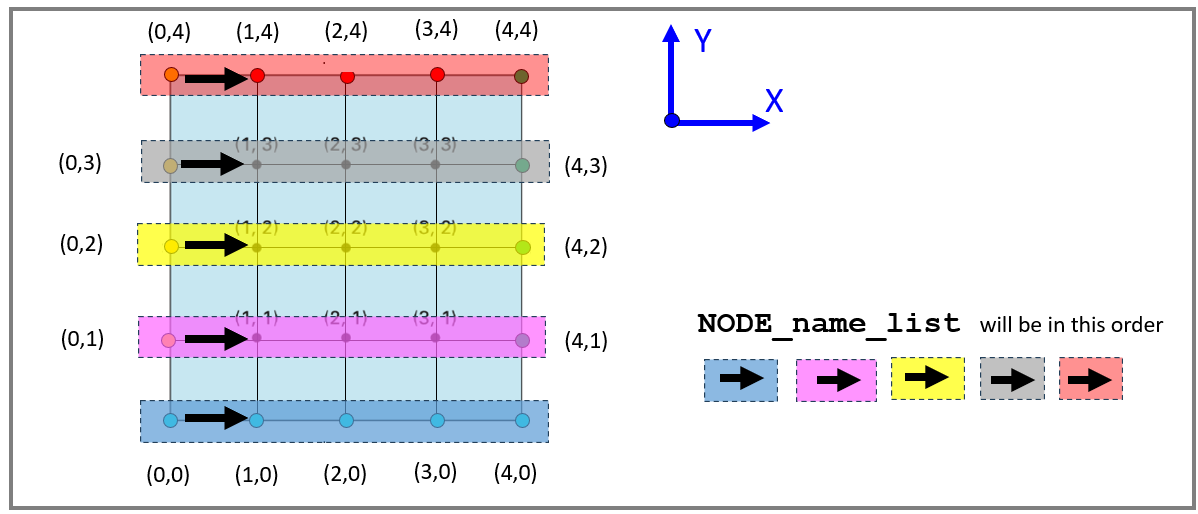

- `NODE_PROP_LOOKUP` as a **table** will have the form

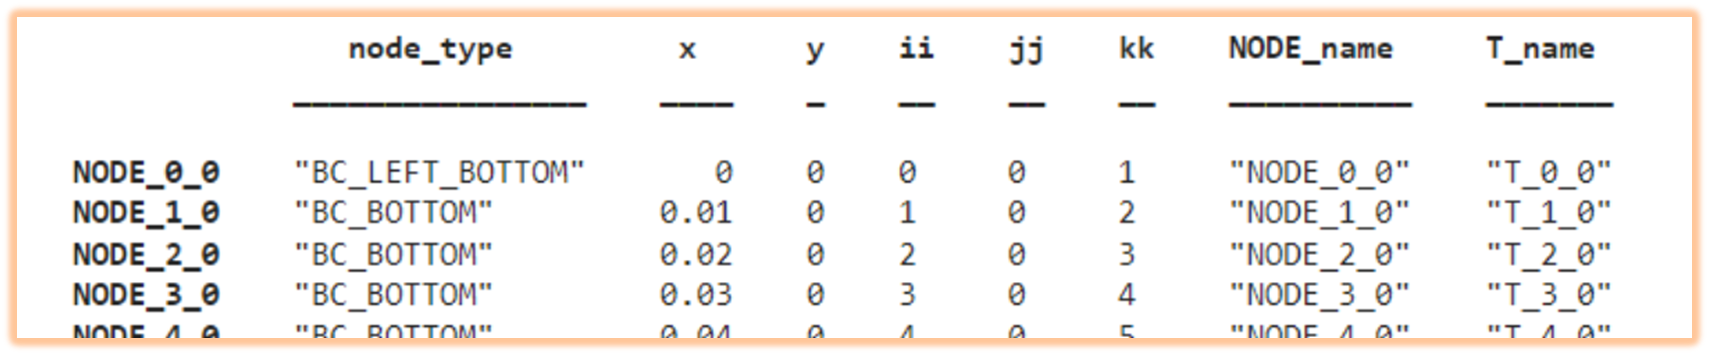

- `NODE_PROP_LOOKUP` as a **dictionary** will have the form

- `NODE_PROP_LOOKUP` as a **cell** will have the form

function [NODE_name_list, NODE_PROP_LOOKUP] = bh_create_node_lookup(x_grid, y_grid, opts_T)
    arguments
        x_grid  (1,:)
        y_grid  (1,:)
        opts_T.mode (1,1) string {mustBeMember(opts_T.mode, ["table", "dictionary", "cell"])} = "table"
    end

    Npt_X = length(x_grid);
    Npt_Y = length(y_grid);

    Ndof  = Npt_X * Npt_Y;   %  is the TOTAL number of grid points in our mesh


Preallocate some label names:

       T_name_list = strings(   Ndof , 1 ); % preallocate TEMPERATURE ID names
    NODE_name_list = strings(   Ndof , 1 ); % preallocate NODE ID names

We'll also preallocate our NODE properties

    PROP_node_type = repmat("UNKNOWN", Ndof, 1);
    PROP_x         = zeros(Ndof, 1);
    PROP_y         = zeros(Ndof, 1);
    PROP_ii        = zeros(Ndof, 1);
    PROP_jj        = zeros(Ndof, 1);
    PROP_kk        = zeros(Ndof, 1);
    PROP_NODE_name = repmat("UNKNOWN", Ndof, 1);
    PROP_T_name    = repmat("UNKNOWN", Ndof, 1);

OK, let's loop over our grid and create our NODE label arrays AND populate our LOOKUP table.  

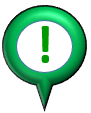**NOTE** we'll create our lists in this order:

-  $\left(\mathit{\mathbf{j}}=0,\;\;i=0\longrightarrow N\right)$           $\left(\mathit{\mathbf{j}}=1,\;\;i=0\longrightarrow N\right)$         $\left(\mathit{\mathbf{j}}=2,\;\;i=0\longrightarrow N\right)$         $\left(\mathit{\mathbf{j}}=3,\;\;i=0\longrightarrow N\right)$  ... etc

- 
$$\left\lbrack T_{0,0} \;\;T_{1,0} \;\;T_{2,0} \;\;T_{3,0} \;\;T_{4,0} \cdots \;\;\;\;\;\;\;T_{0,1} \;\;T_{1,1} \;\;T_{2,1} \;\;T_{3,1} \;\;T_{4,1} \cdots \;\;\;\;\;\;T_{0,2} \;\;T_{1,2} \;\;T_{2,2} \;\;T_{3,2} \;\;T_{4,2} \cdots \;\;\;\;\;\;\;T_{0,3} \;\;T_{1,3} \;\;T_{2,3} \;\;T_{3,3} \;\;T_{4,3} \cdots \;\;\;\;\;\;\;\;T_{0,4} \;\;T_{1,4} \;\;T_{2,4} \;\;T_{3,4} \;\;T_{4,4} \cdots \right\rbrack$$


- where:   $T_{i\;\;,\;j} \;=T\left(x_i \;,y_j \right)$

    count =0;
    for jj_ID=0:(Npt_Y-1)
        for ii_ID=0:(Npt_X-1)
    
            count                 = count + 1;
            T_name_list(count)    = "T_"    + ii_ID + "_" + jj_ID;
            NODE_name_list(count) = "NODE_" + ii_ID + "_" + jj_ID;
            
            % CLASSIFY the node
            if( (ii_ID > 0) && (ii_ID < (Npt_X-1)) && (jj_ID > 0) && (jj_ID <(Npt_Y-1)) )
               NODE_TYPE = "INTERNAL";
            else
                 if(     jj_ID==0 )  % *** BOTTOM ***
    
                         if(    ii_ID==0)
                            NODE_TYPE = "BC_LEFT_BOTTOM";
                         elseif(ii_ID==(Npt_X-1))
                            NODE_TYPE = "BC_RIGHT_BOTTOM";
                         else
                            NODE_TYPE = "BC_BOTTOM";
                         end
    
                 elseif( jj_ID==(Npt_Y-1)  ) % *** TOP ***
                         if(    ii_ID==0)
                            NODE_TYPE = "BC_LEFT_TOP";
                         elseif(ii_ID==(Npt_X-1))
                            NODE_TYPE = "BC_RIGHT_TOP";
                         else
                            NODE_TYPE = "BC_TOP";
                         end
    
                 elseif( ii_ID==0 ) % *** LEFT ***                
                       NODE_TYPE = "BC_LEFT";  
    
                 elseif( ii_ID==(Npt_X-1) ) % *** RIGHT ***
                       NODE_TYPE = "BC_RIGHT";
    
                 else
                     error("###_ERROR:  UNknown NODE type");
                 end
            end % CLASSIFY the node
    
            % populate our lookup properties
            PROP_node_type(count) = NODE_TYPE;
            PROP_x(count)         = x_grid(ii_ID+1);
            PROP_y(count)         = y_grid(jj_ID+1);
            PROP_ii(count)        = ii_ID;
            PROP_jj(count)        = jj_ID;
            PROP_kk(count)        = count;
            PROP_NODE_name(count) = NODE_name_list(count);
            PROP_T_name(count)    = T_name_list(count);            
        end
    end

Create a data TABLE

    my_table           = table;
    
    my_table.node_type = PROP_node_type;
    my_table.x         = PROP_x;
    my_table.y         = PROP_y;
    my_table.ii        = PROP_ii;
    my_table.jj        = PROP_jj;
    my_table.kk        = PROP_kk;
    my_table.NODE_name = PROP_NODE_name;
    my_table.T_name    = PROP_T_name;
    
    % Lastly, add RowNames to our node LOOKUP table
    my_table.Properties.RowNames = NODE_name_list;

Free up some memory

    clear  PROP_node_type    
    clear  PROP_x
    clear  PROP_y
    clear  PROP_ii
    clear  PROP_jj
    clear  PROP_kk
    clear  PROP_NODE_name
    clear  PROP_T_name

Now take care of the output

    if("table" == opts_T.mode)
          NODE_PROP_LOOKUP = my_table;
    elseif("cell" == opts_T.mode)
         % return an N_x_1 column  where C{kk,:} = { 1x8 cell }

          tmp_C            = table2cell(my_table);
          N_rows           = height(my_table);
          NODE_PROP_LOOKUP = mat2cell(tmp_C, ones(N_rows,1), width(my_table) );
    elseif("dictionary" == opts_T.mode)
          % tmp_C            = table2cell(my_table);
          % N_rows           = height(my_table);
          % NODE_CELL = mat2cell(tmp_C, ones(N_rows,1), width(my_table) );
          % NODE_PROP_LOOKUP = dictionary( NODE_name_list(:), ...
          %                                NODE_CELL       );

          NODE_PROP_LOOKUP = dictionary( NODE_name_list(:), table2struct(my_table)  );
    end

end  % function

Copyright 2024 The MathWorks®, Inc.